# RBE500: Foundations of Robotics 

# Week 9 : Configuration Space 

**Kathia Coronado**

*Robotics Engineering Graduate Student, Worcester Polytechnic Institute, Worcester, Massachussets, kcoronado@wpi.edu*

## Introduction

This week's assignment focused analyzing a robotic system's workspace and configuration space. The goal of this assignment was to analyze a planar robot by adding radom obstacles in its worskpace and then mapping its configuration space. This assignment was inspired by Dr. Alterovitz's application, see figure 1, that maps the robot's workspace state to the configuration space. Using his program as a model, we were tasked with visualizing the robots workspace with and without obstacles and then mapping this to the configuration space of the system. 

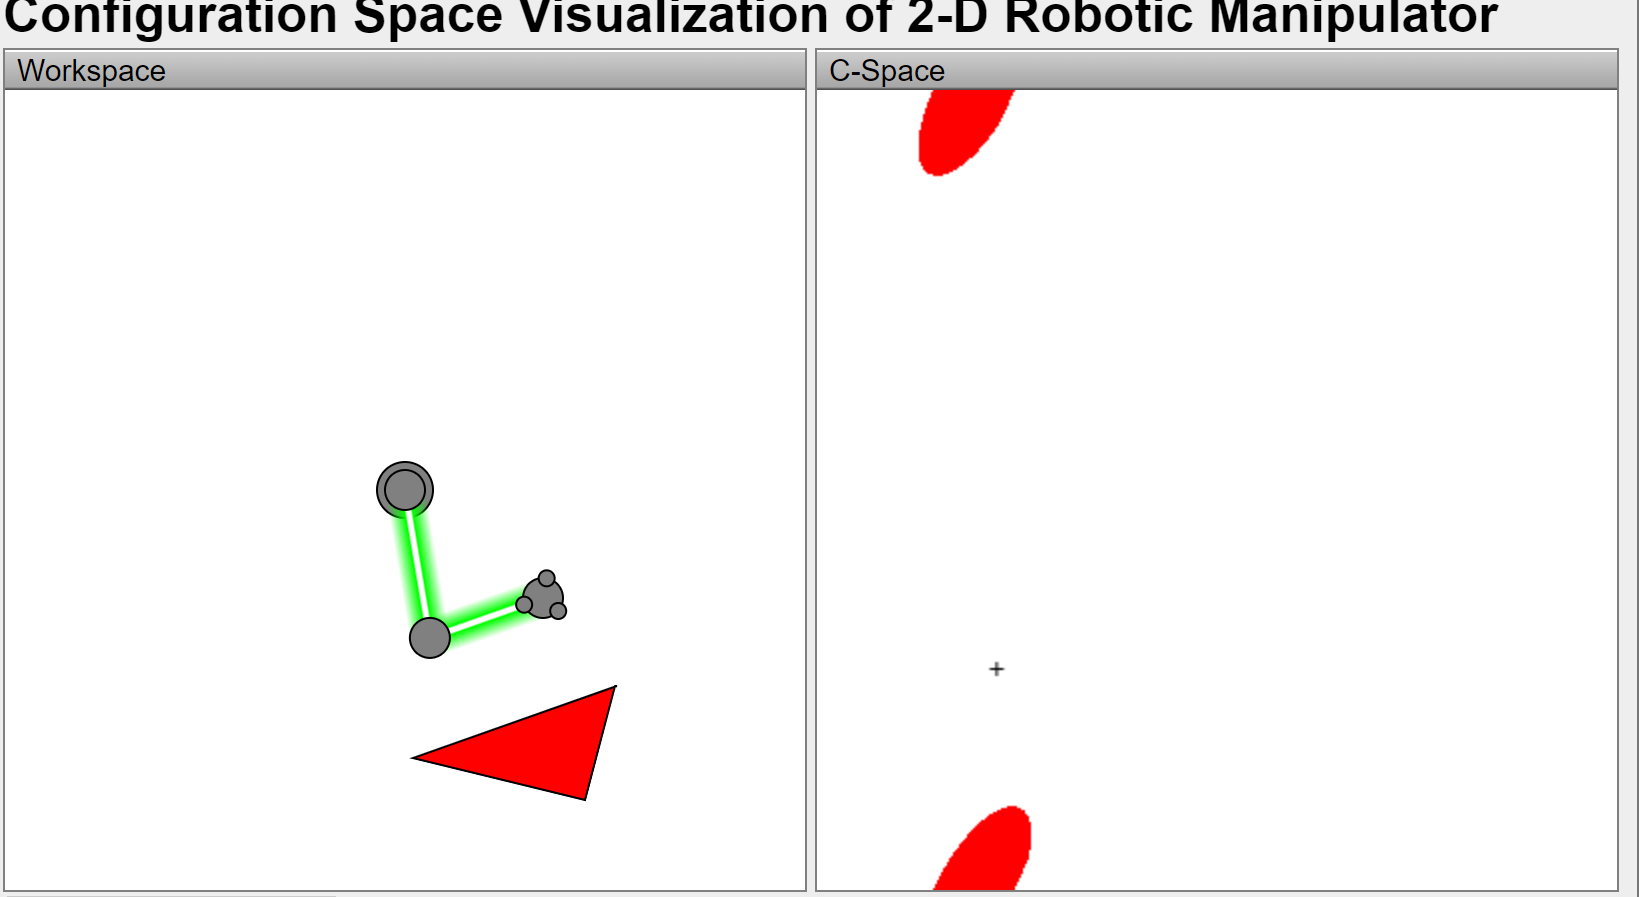

Figure 1 - Workspace and configuration space of a 2 link planar robot 

## **Methods  and Materials**

**Answer :**


$$T_{01} =\left(\begin{array}{cccc}
\cos \left(\frac{\pi \,q_1 }{180}\right) & -\sin \left(\frac{\pi \,q_1 }{180}\right) & 0 & \cos \left(\frac{\pi \,q_1 }{180}\right)\\
\sin \left(\frac{\pi \,q_1 }{180}\right) & \cos \left(\frac{\pi \,q_1 }{180}\right) & 0 & \sin \left(\frac{\pi \,q_1 }{180}\right)\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right)$$



$$T_{02} =\left(\begin{array}{cccc}
\cos \left(\frac{\pi \,{\left(q_1 +q_2 \right)}}{180}\right) & -\sin \left(\frac{\pi \,{\left(q_1 +q_2 \right)}}{180}\right) & 0 & \cos \left(\frac{\pi \,{\left(q_1 +q_2 \right)}}{180}\right)+\cos \left(\frac{\pi \,q_1 }{180}\right)\\
\sin \left(\frac{\pi \,{\left(q_1 +q_2 \right)}}{180}\right) & \cos \left(\frac{\pi \,{\left(q_1 +q_2 \right)}}{180}\right) & 0 & \sin \left(\frac{\pi \,{\left(q_1 +q_2 \right)}}{180}\right)+\sin \left(\frac{\pi \,q_1 }{180}\right)\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right)\mathrm{}$$


This weeek's assignment involved analyzing andvisualizing a planar robot's work space, see figure 2, and configuration space.  Workspace is the eviroment in which the robot is operating with. The worskspace can include obstacles and other contrainsts that could be imposed onto the system. For the purpose of the assignment, I created a workspace that had two obstacles that interfere or limite the movement of the robot arm. The obstacles that I chose for this assignment was a square and a circle. Using this workspace, I then plotted the configuration space. The configuration space plot the joint variable configurations that that are not allowable for the robot; this could be due to obstable or physical constrainst of the robots. 

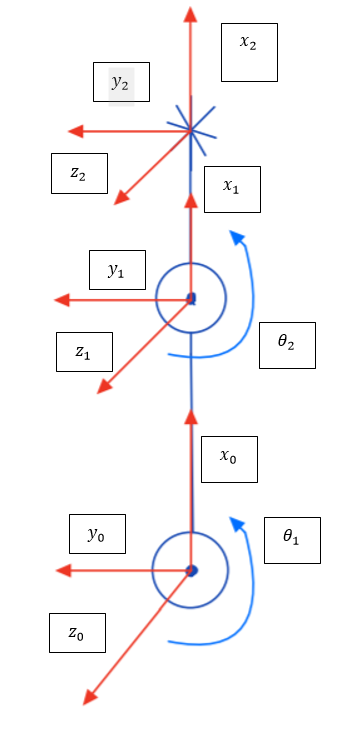

Figure 2 - Simplified diagram of Robot arm

In order to begin the workspace and configuration space analysis, a robotic arm analysis must be conducted. One must first understand their system in order to understand its constrainsts. For this reason, a forward kinematic analysis was conducted on the system. Knowing the forward kinematics alwos us to understand the position of the link with respect to the world it is opperating in. 

.For this analysis, the DH method was used to obtain the tranformation matrices. The DH method simplifies the analysis of a multi link manipulator by representing each HTM, , as a product of four basic tranformations, see equation 3.10.

In order to use the DH method, one must first analyze the system and obtain the link length ( ), link twist ( ), link offset ( ) and joint angle (). For this problem these DH parameters were obtained and displayed on table 1.

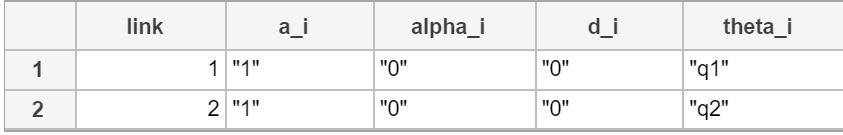

Table 1 : DH parameters for the system 

Using these parameters equation 3.10, in the textbook can be used to obtain the homogeneous tranformation matrix for each of the links in the system, see equations 1a -b. Substituting the DH parameters in equations, with the appropriate and corresponding link parameters in table 1, the homogeneous transformation matrices for each link in the system can be determined

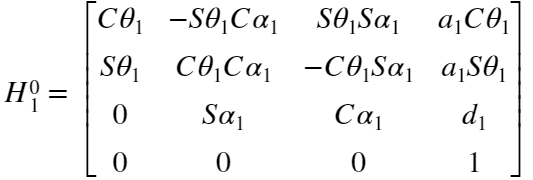                                                                                            (1a)

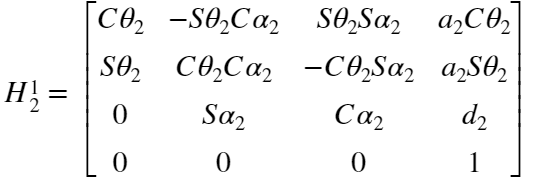                                                                                            (1b)

Using this and some other relationships (such as the order of attachment), the Homogenous transformation matrices were defines for each each joint with respect to the base, see equations,2a - b

                                                                                                                                                  (2a)

                                                                                                                                             (2b)

Now that the transformation matrices for the system with respect to the base have beeen calculated, the work space for the system can be determiend and plotted. The first portion of this assignment involved plotting the the work space of the robot arm in an environment with no obstacles . In order to accomplish this, I did a sweep of the joint values from 0 to 360 degrees and then substitued  those angles into the symbolic equations of the HTM of the first link with respect to the base and of the end effector with respect to the base, see equation 3a-3b. Once I substited these values I extracted the position vector of both matrices at each configuration and then plotted these positions, view plot 1.

  =                                                                                                                                               (3a)

  =                                                                                                                                               (3b)

The second portion of this assignment involved analyzing the workspace of the robot in an environment with obstacles. In order to accomplish this task, I first made circular and rectangular regions to serve as obstacles for the robot. I then made a for loop where i iterate over every permutation of the joints angles in order to solve for the end of link positionf of the arm at these angles. In this loop I placed a few condition statements that allowed me to mark the areas that the robot arm would not be able to access due to the obstacles. The conditional tested if any of the points of the robot's workspace coincided with the obstacles, once this condition was met, I plottted the "no go" zones with red x. I also stored alll of the "bad" angles associated with these unreachable positions, as they are crucial for solving for the configuration space of the robot. 

The thrid portion of this assignmentt involved mapping the configuration space for the the system in the environment with obstacles. In order to accomplish this task I used the joint variable configurations that I found collided with the obstacles, and then I plotted these variables in a joint 2 Vs Joint 1 plot, see plot 3. 

## **Results**

In the code exerpt below, I first define my symbolic variables. 

q1 and q2 are the joint variables. and l1 and l2 are the link lengths

clc; clear;
syms q1 q2
l1 =1 ;
l2 = 1 ;


In order to use the DH method, one must first analyze the system and obtain the link length ( ), link twist ( ), link offset ( ) and joint angle (). For this problem these DH parameters were obtained and displayed on the table below.

a = [l1; l2];
alpha = [0; 0];
d = [ 0; 0];
theta = [q1; q2];
A = GetDH(a, alpha, d, theta);
%A =GetDHrad(a, alpha, d, theta);
n_links = length(theta

Call out function that uses DH parameters to find the homogeneous transformation matrix using the the DH method. A is a cell array that holds all of the  sequential HTM for the system

DH_tab = DH_table(n_links,a , alpha, d, theta) % TABLE 

DH_tab = 2×5 table
    link    a_i    alpha_i    d_i    theta_i
    ____    ___    _______    ___    _______

     1      "1"      "0"      "0"     "q1"  
     2      "1"      "0"      "0"     "q2"  


Using these sequetial HTMs calcualted above, the HTM for each frame with respect to the base frame can be calculated. To obtain these HTMs, the sequential HTMs must be postmultiplied in order, from the base to the target frame.

T01 = simplify(A{1})

$$T01 = \left(\begin{array}{cccc} \cos\left(\frac{\pi \,q_{1}}{180}\right) & -\sin\left(\frac{\pi \,q_{1}}{180}\right) & 0 & \cos\left(\frac{\pi \,q_{1}}{180}\right)\\ \sin\left(\frac{\pi \,q_{1}}{180}\right) & \cos\left(\frac{\pi \,q_{1}}{180}\right) & 0 & \sin\left(\frac{\pi \,q_{1}}{180}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T02 = simplify(A{1}*A{2})

$$T02 = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & -\sigma_{1} & 0 & \sigma_{2}+\cos\left(\frac{\pi \,q_{1}}{180}\right)\\ \sigma_{1} & \sigma_{2} & 0 & \sigma_{1}+\sin\left(\frac{\pi \,q_{1}}{180}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\frac{\pi \,\left(q_{1}+q_{2}\right)}{180}\right)\\ \sigma_{2}=\cos\left(\frac{\pi \,\left(q_{1}+q_{2}\right)}{180}\right) \end{array}$$

Joint variables array of values. 

q1t =linspace(0,360,45);
q2t =linspace(0,360,45);


### Part 1 

Plotting the workspace of the robot arm  in an environment without obstacles. 

In plot 1, blue represents the worspace of the end of link 2 and green is the tip of the link 2 of the end effector 

First I set up a nested loop through all of the permutations of posible joint angles. In each iteration a different combination of joint angles are plotted 

% Part 1 
% Let's just get the sweep the angles and plot position of end of links 
part1 = figure 

part1 =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


for i= 1:length(q1t)
    for j = 1:length(q2t)
        
        q =[q1t(i),q2t(j)];
        

In this analysis I extract the position vector of the transformation matrices in order to plot the work space of the the tips of both links.

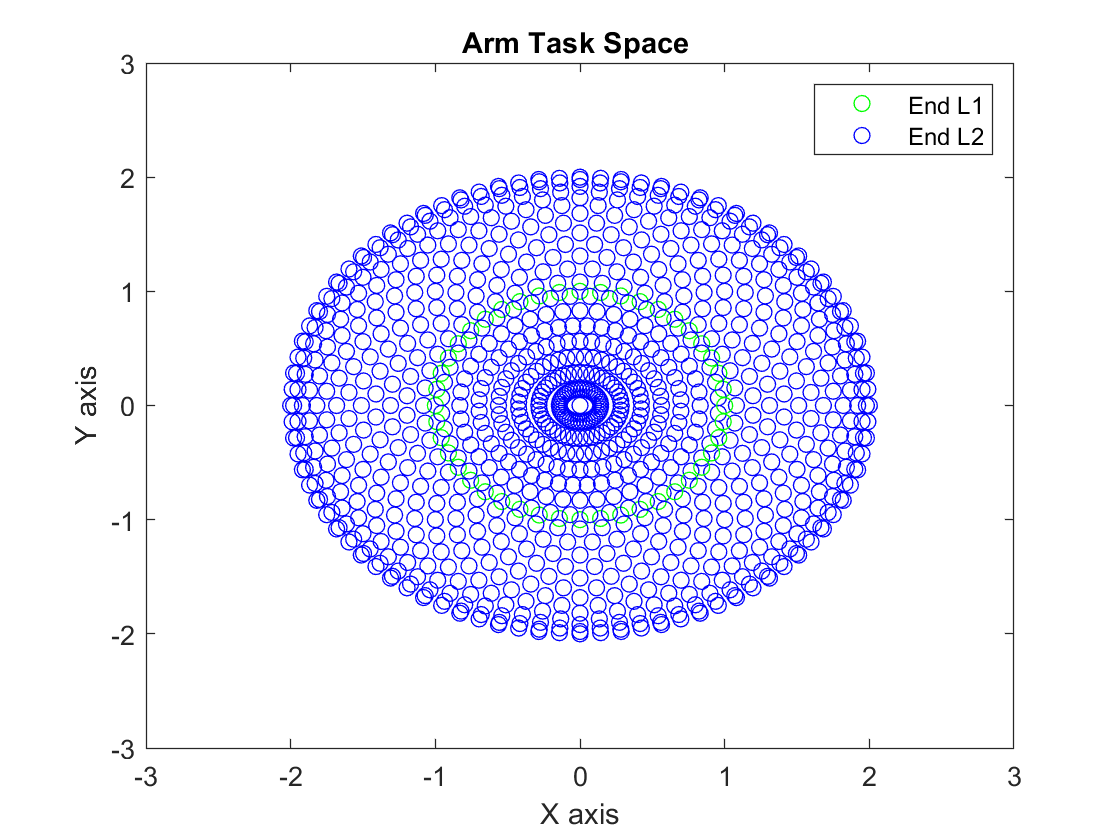

        T01_val = subs(T02(1:3,4),[q1,q2], q).';
        x01 = double(T01_val(1));
        y01 = double(T01_val(2));
        
        T02_val=subs(T01(1:3,4),[q1,q2], q).';
        x02 = double(T02_val(1));
        y02 = double(T02_val(2));
        
        
        plot(T01_val(1),T01_val(2),'bO')
     
        plot(T02_val(1),T02_val(2),'gO')
        
        xlim([-3, 3]);
        ylim([-3,3]);
        hold on 
    end
end
xlabel ('X axis')
ylabel('Y axis')
legend('End L1', 'End L2')
title('Arm Task Space ')
hold off 

### Part 2 

This section of the assingment analyzes the workspace of the robot arm in an environment with obstacles 

% Part 2
%lets gets the work space with obstacle

First I plot the obstacles, rectangle and circle, and mark then as red regions 

part2 = figure

part2 =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


pgon = polyshape([0.5 0.5 2 2],[2 0.5 0.5 2]);
plot(pgon, 'FaceColor','red','FaceAlpha',0.2)
hold on 

circ = nsidedpoly(1000, 'Center', [-1,-1], 'Radius', 0.5);
plot(circ, 'FaceColor', 'r','FaceAlpha',0.2)
hold on

THese two arrays will hold the joint angle configurations associated with the no go zones 

badq1 = NaN(length(q1t),1);
badq2 = NaN(length(q1t),1);

Nest for loop to obtain the positon of the end of the links at all the permutations of the joint angles

it = 0;
for i= 1:length(q1t)
    for j = 1:length(q2t)
        
        q =[q1t(i),q2t(j)];
        
        T01_val = subs(T02(1:3,4),[q1,q2], q).';
        x01 = double(T01_val(1));
        y01 = double(T01_val(2));
        
        T02_val=subs(T01(1:3,4),[q1,q2], q).';
        x02 = double(T02_val(1));
        y02 = double(T02_val(2));
        

THis is a conditional statement that analyzes if any of the confgurations of the robot would lead to a collision with  an obstacle. If the point and the obstacle region intersect, then i highlight these positions with red to ensure that they are" no go zones.". I also store all of the angles associated with these bad regions .

If the region and the position do no intersect then i plot the workspace position in blue. 

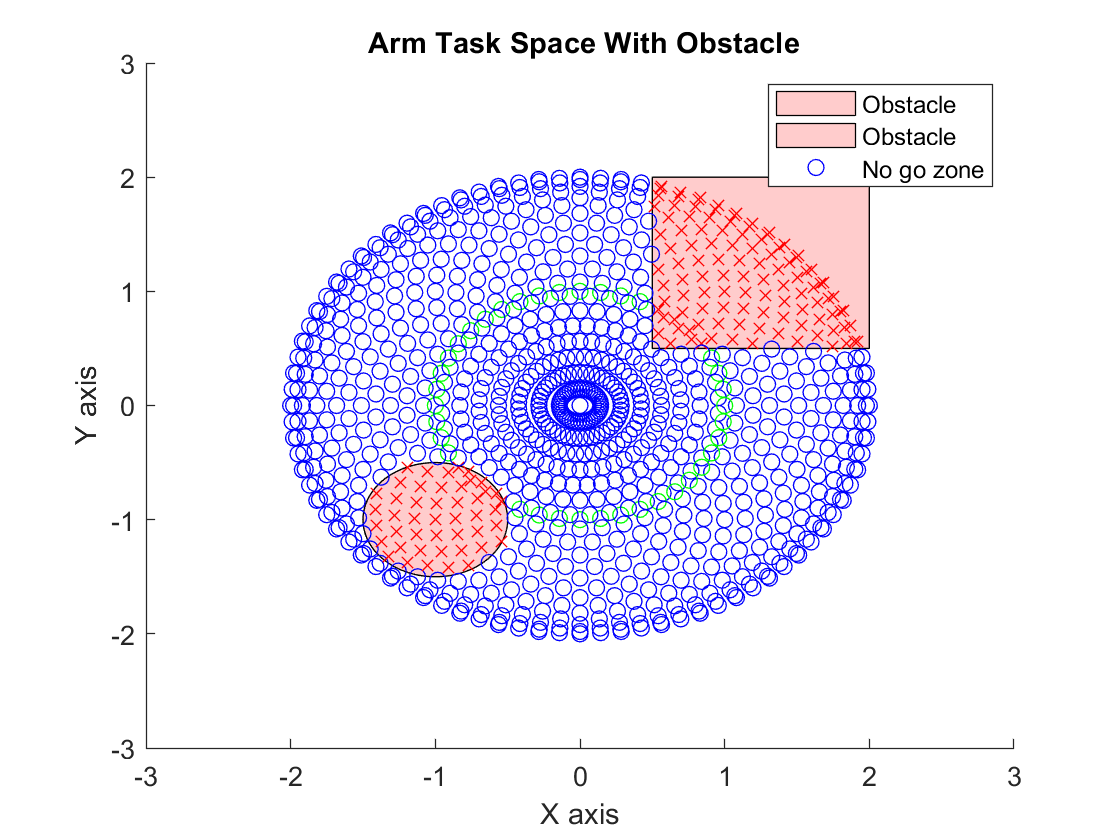

        
        if isinterior(pgon,x01,y01) ||  isinterior(circ,x01,y01)
            it = it + 1;
            plot(T01_val(1),T01_val(2),'rx')
            bp = 1 ;
            badq1(it) = q(1);
            badq2(it) = q(2);
            
        else
            plot(T01_val(1),T01_val(2),'bO')
            bp = 0;
        end
        
        if isinterior(pgon,x02,y02) ||  isinterior(circ,x02,y02)
            plot(T02_val(1),T02_val(2),'rx');
            if bp  == 0 
                it = it + 1;
                bp = 1 ;
                badq1(it) = q(1);
                badq2(it) = q(2);
            end
        else
            plot(T02_val(1),T02_val(2),'gO')
            
        end
        xlim([-3, 3]);
        ylim([-3,3]);
        hold on 
    end
end
xlabel ('X axis')
ylabel('Y axis')
legend('Obstacle', 'Obstacle', 'No go zone')
title(' Arm Task Space With Obstacle')


hold off 

### Part 3 

Plotting of the configuration space. In order to accomplish this, I simply take the joint values associated with the " no go zones" and then I  plot them against each other to view the configurations in which the robot cannot do.

% Part 3 
%Configuration space 

part3 =   Figure (6) with properties:

      Number: 6
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


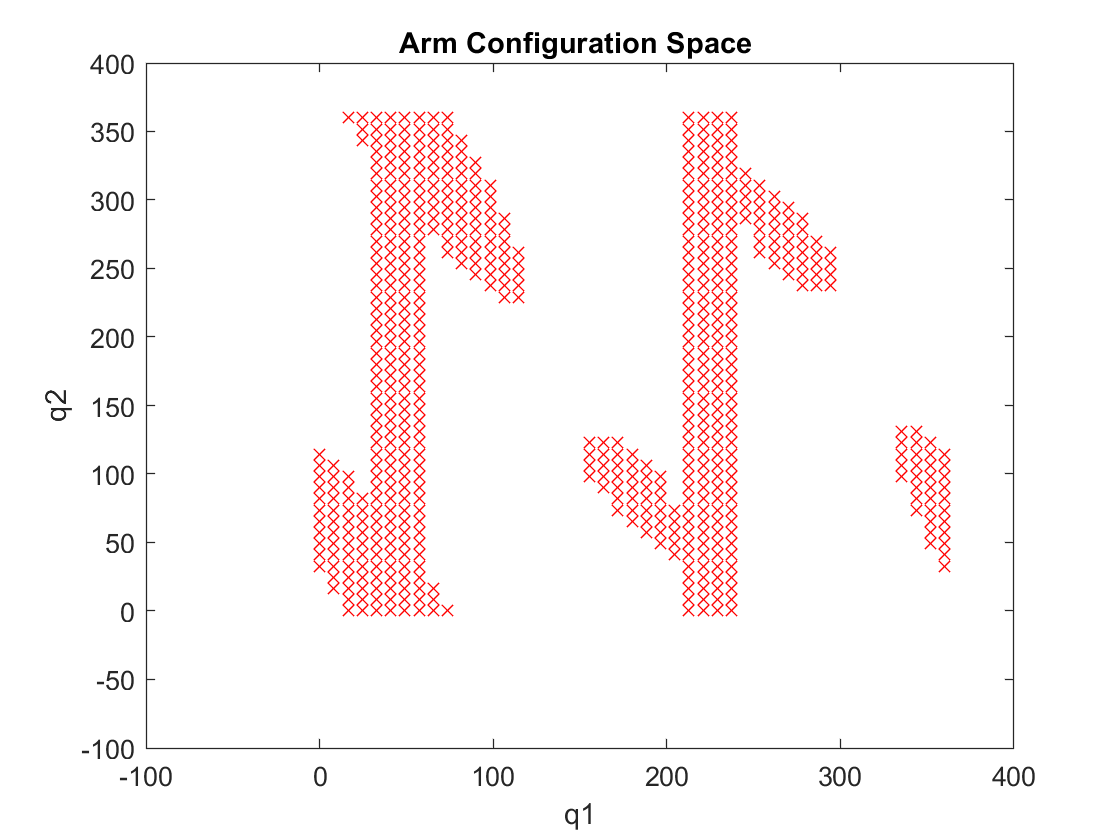

part3 = figure 
plot(badq1,badq2, 'rX')
title('Arm Configuration Space ')
xlabel('q1')
ylabel('q2')
xlim([-100, 400]);
ylim([-100, 400]);

function A = GetDH (a, alpha,d,theta)
A = {};
%theta = theta*180/pi;
for i = (1:length(a))
    
    H = [ cosd(theta(i)) -sind(theta(i))*cosd(alpha(i)) sind(theta(i))*sind(alpha(i)) a(i)*cosd(theta(i));
         sind(theta(i)) cosd(theta(i))*cosd(alpha(i)) -cosd(theta(i))*sind(alpha(i)) a(i)*sind(theta(i));
         0 sind(alpha(i)) cosd(alpha(i)) d(i);
         0 0 0 1];
    A{i}= simplify((H));
end
end

function [T] = DH_table(n_links, a_i, alpha_i, d_i, theta_i)
% Author: Brian Evarts
% Function to create DH table for display
% Returns: A DH Table with strings as values for IMRD display puroses
    link = linspace(1,n_links, n_links)';   
    a_i_str = string(a_i);
    alpha_i = string(alpha_i);
    d_i_str = string(d_i);
    theta_i_str = string(theta_i);
    T = table(link, a_i_str,alpha_i, d_i_str,theta_i_str, 'VariableNames', {'link','a_i', 'alpha_i' 'd_i', 'theta_i'});
    
end 


## Discussion

THe main focus of this assignmnet was to get more familiar and gain a better understanding of the workspace and configuration space. IT involved analyzing and robot and then plottig these space in order to understand it all visually. For my submission i analyzed the workspace of the robot when there are two obstacles in the way of the robot.  I then plotted the workspace and the plotted the configuration space. 

All in  all, this was a very interesting and stimulating assingment, i really enjoyed learning more about matlab and its useful functions that aid in the analysis of robotic systems. MY favorite function, that I used in my assignment was the isinterior function, which returns a boolean after discerining of a point lies within a specified region. 

## References

(1) Spong et al. (2020).* Robot Modeling and Control *(2nd Edition). Wiley.